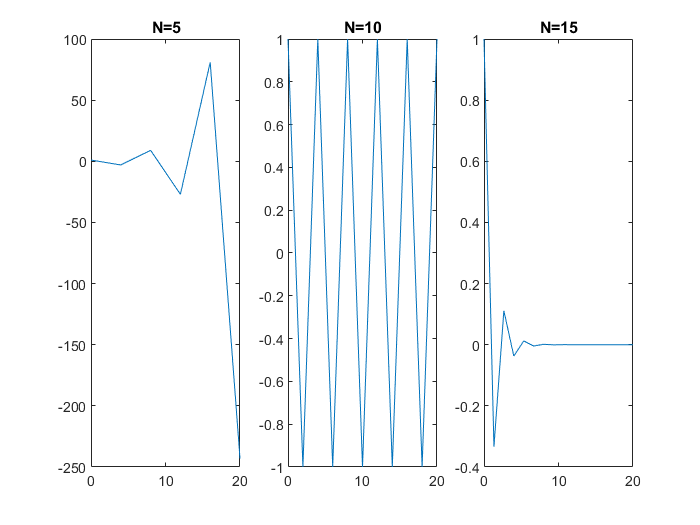

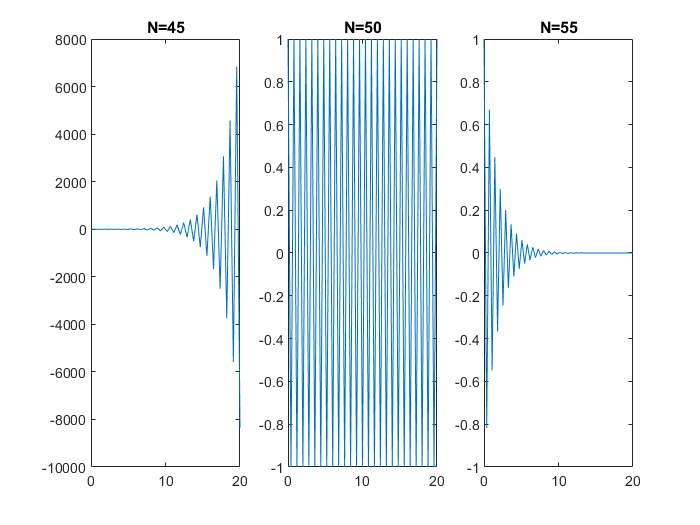

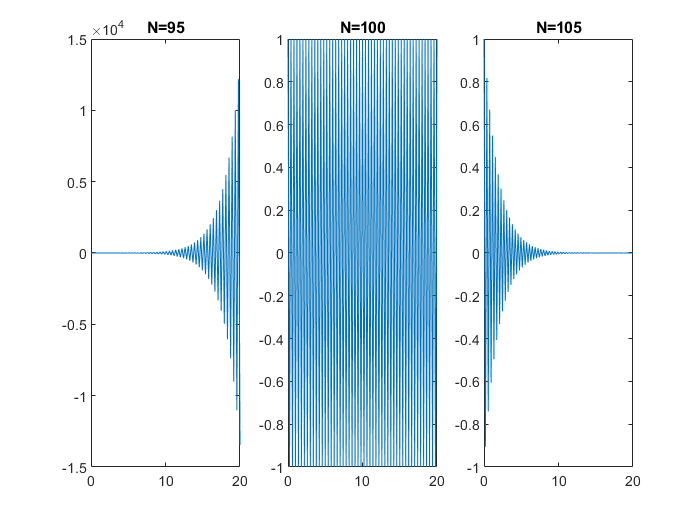

clear all
close all
lambda=[-1 -5 -10];
T=20;t0=0;y0=1;
for a=lambda
    f1=@(t,y) a*y;
    figure
    for i=-1:1
        h=2/(abs(a)+i/2);
        N=(T-t0)/h;
        [tn,un,h]=euleroEspl(f1,t0,T,y0,N);
        subplot(1,3,i+2)
        plot(tn,un)
        title("N="+N)
    end
end

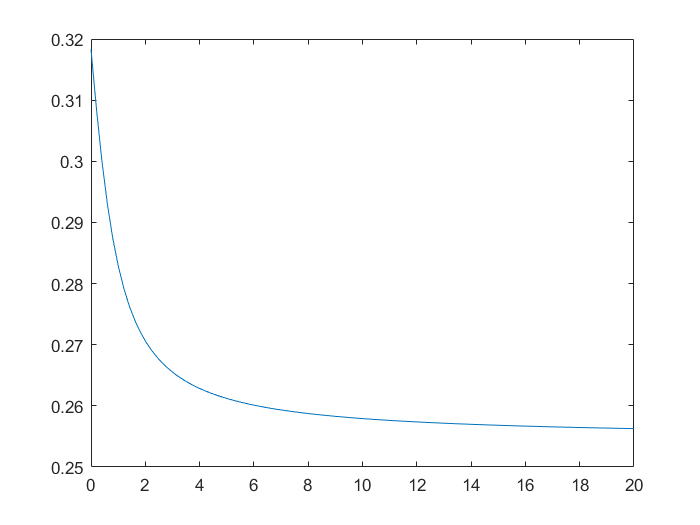

clear all
close all
f1=@(t,y) -(atan(t)+2*pi)*y;
t0=0;T=20;y0=1;
lambda=@(t) atan(t)+2*pi;
h=@(t) 2./abs(lambda(t));
plot(linspace(t0,T,100),h(linspace(t0,T,100)))

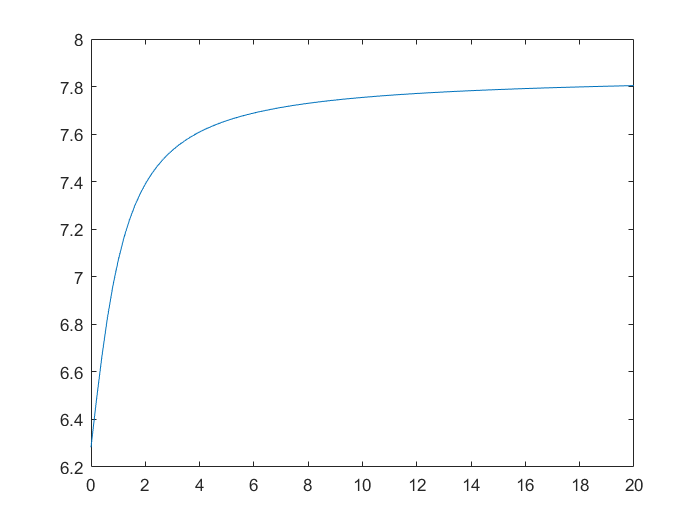

plot(linspace(t0,T,100),lambda(linspace(t0,T,100)))

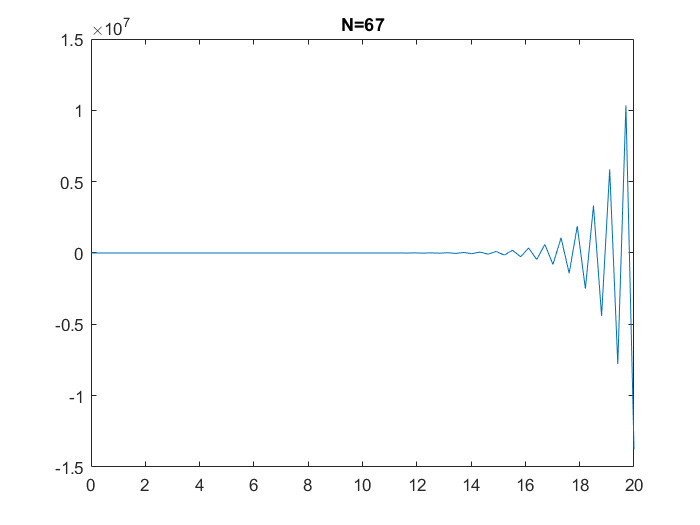

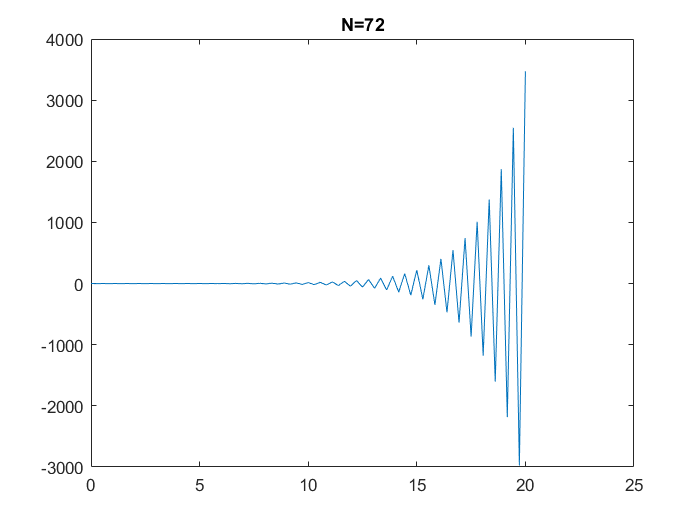

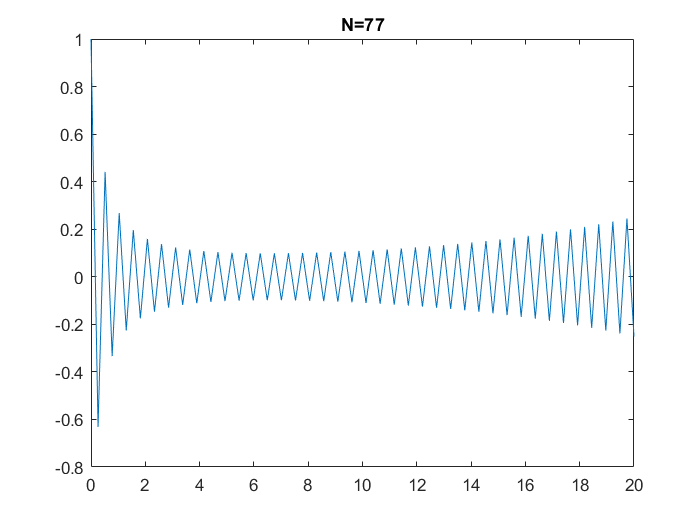

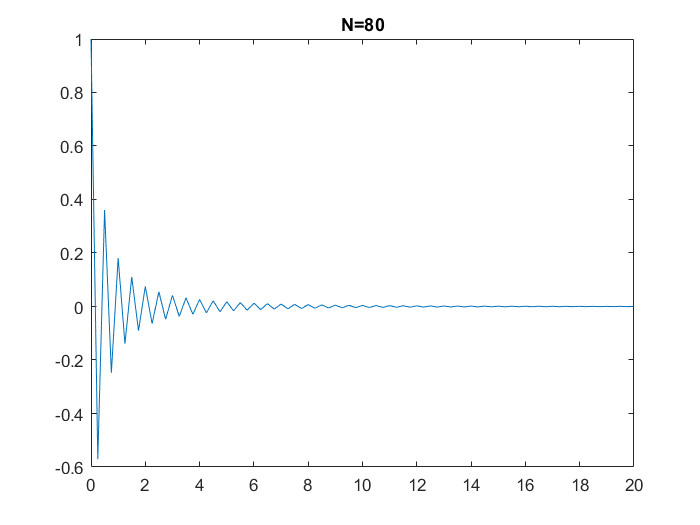

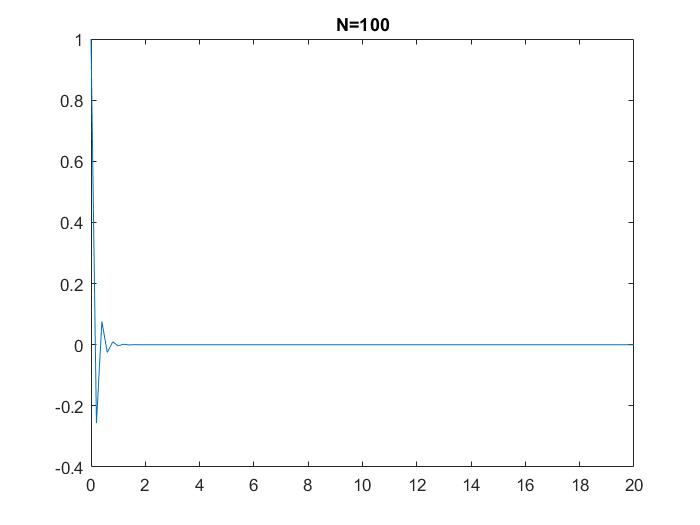

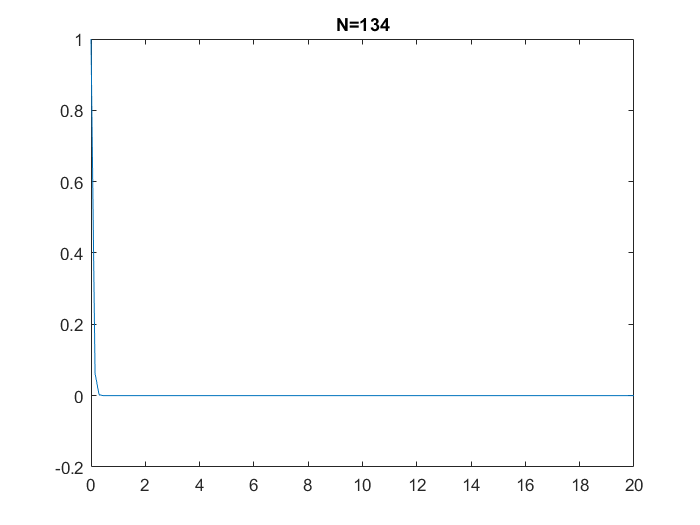

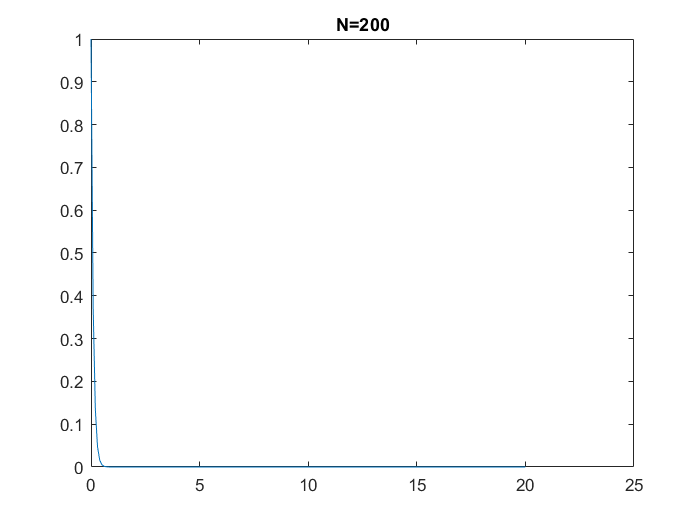

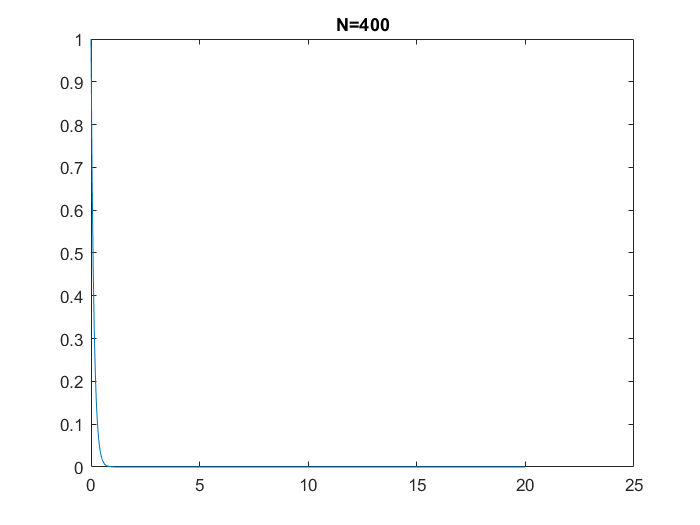

N=[67,72,77,80,100,134,200,400];
for n=N
    figure
    [tn,un]=euleroEspl(f1,t0,T,y0,n);
    plot(tn,un)
    title("N="+n)
end

clear all
close all
syms y;
f=(4*y^2)/(1+y^2)-4*y;
fp=-(4*y^2)/(1+y^2)-4*y;
fp1=diff(fp);
f1=diff(f)

$$f1 = \frac{8\,y}{y^{2}+1}-\frac{8\,y^{3}}{{\left(y^{2}+1\right)}^{2}}-4$$

h=2/abs(f1)

$$h = \frac{2}{\left|\frac{8\,y^{3}}{{\left(y^{2}+1\right)}^{2}}-\frac{8\,y}{y^{2}+1}+4\right|}$$

N=50/h

$$N = 25\,\left|\frac{8\,y^{3}}{{\left(y^{2}+1\right)}^{2}}-\frac{8\,y}{y^{2}+1}+4\right|$$

hp=2/abs(fp1)

$$hp = \frac{2}{\left|\frac{8\,y}{y^{2}+1}-\frac{8\,y^{3}}{{\left(y^{2}+1\right)}^{2}}+4\right|}$$

Np=50/hp

$$Np = 25\,\left|\frac{8\,y}{y^{2}+1}-\frac{8\,y^{3}}{{\left(y^{2}+1\right)}^{2}}+4\right|$$

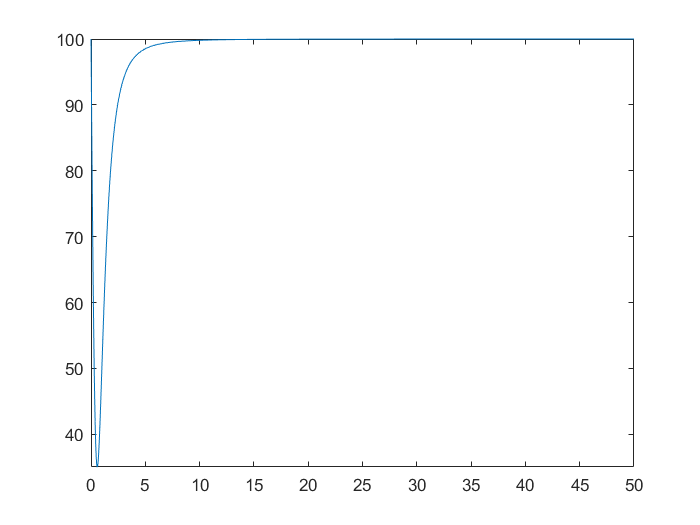

fplot(N,[0 50])

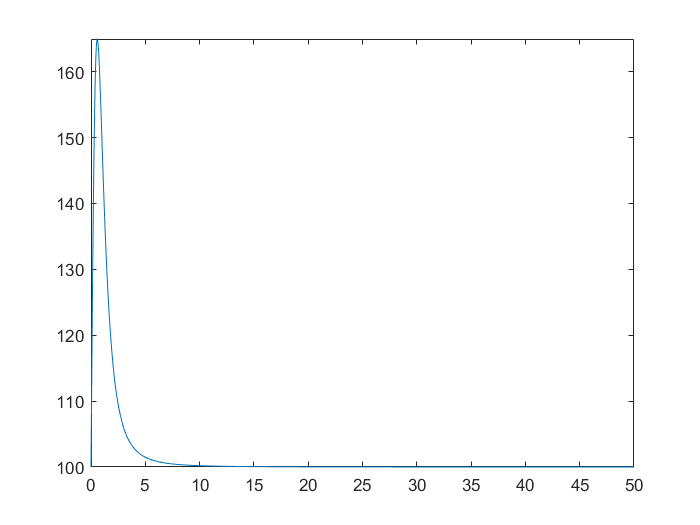

fplot(Np,[0 50])

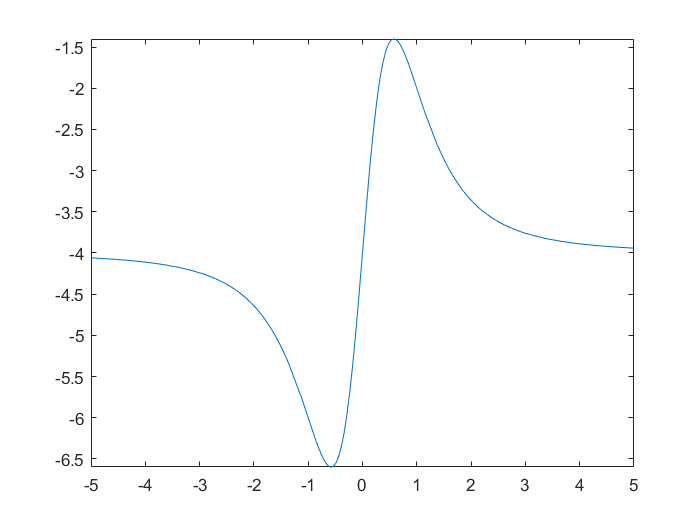

fplot(matlabFunction(f1))

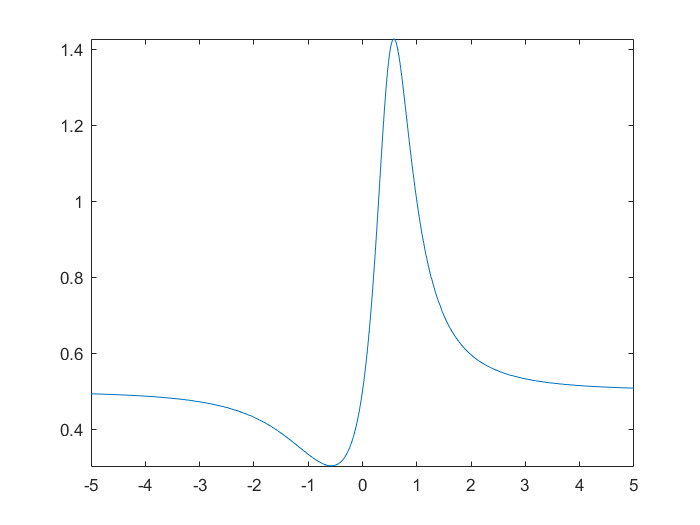

fplot(matlabFunction(h))

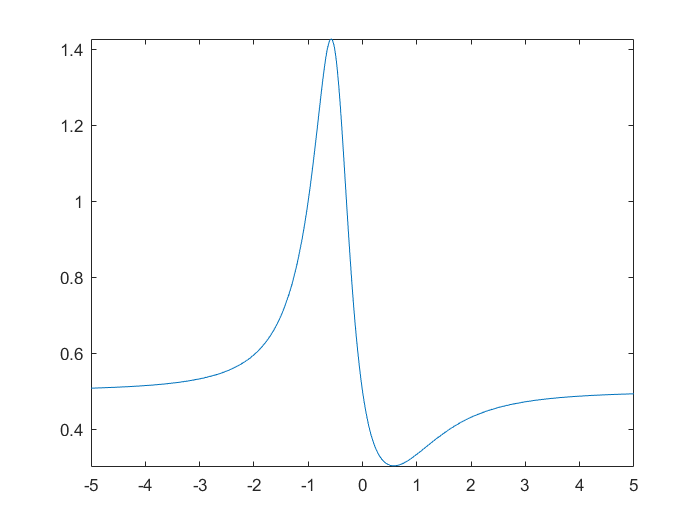

fplot(matlabFunction(hp))

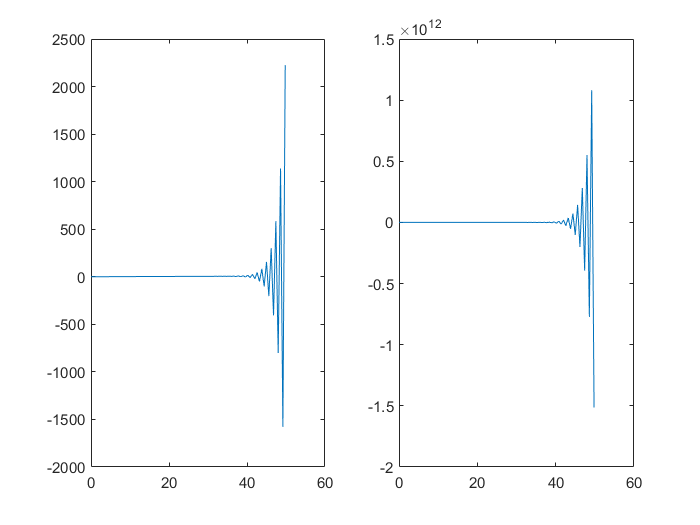

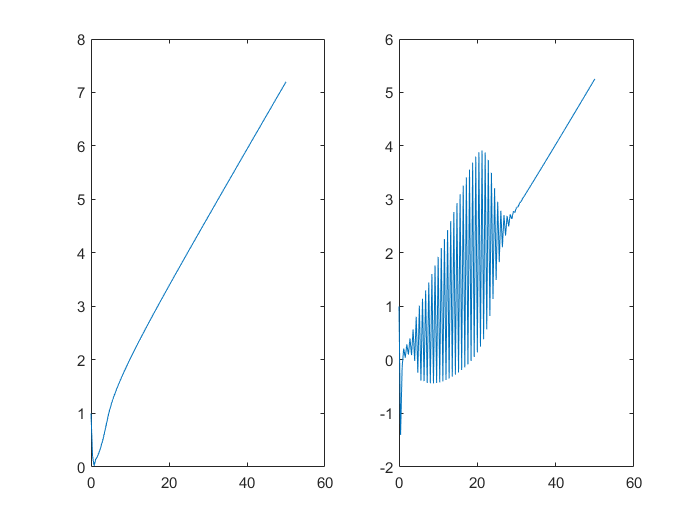

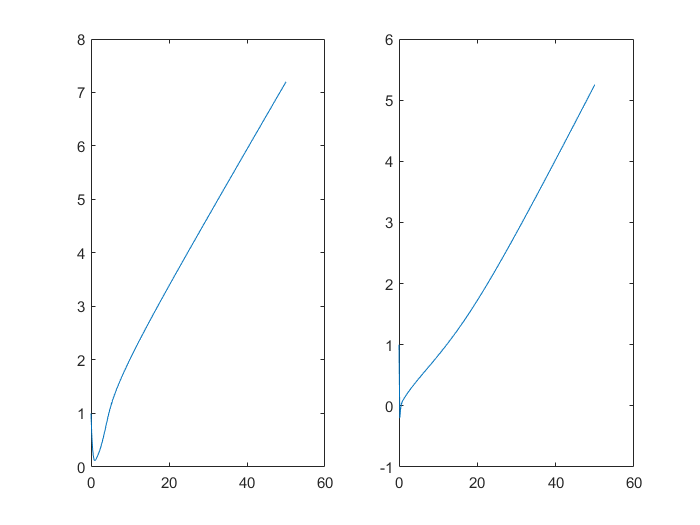

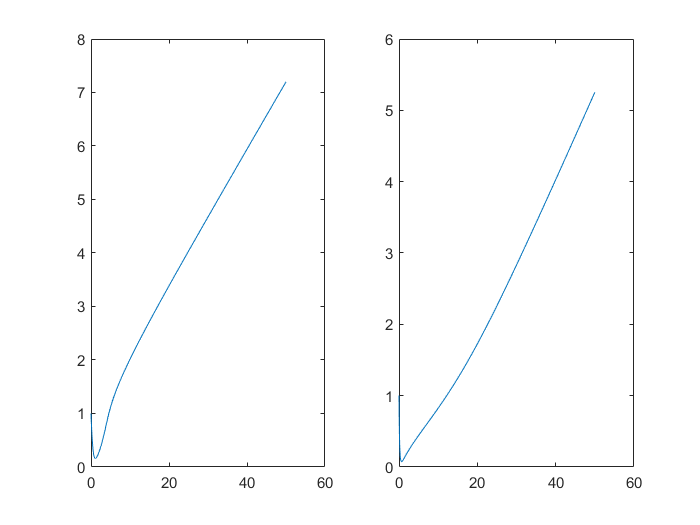

f=@(t,y) (4*y.^2)./(1+y.^2)-4*y+t./2;
fp=@(t,y) -(4*y.^2)./(1+y.^2)-4*y+t./2;
t0=0;T=50;y0=1;
for h=[0.6 0.4 0.2 0.05]
    figure
    N=(T-t0)/h;
    [tn,un]=euleroEspl(f,t0,T,y0,N);
    [tnp,unp]=euleroEspl(fp,t0,T,y0,N);
    subplot(1,2,1)
    plot(tn,un)
    subplot(1,2,2)
    plot(tnp,unp)
end